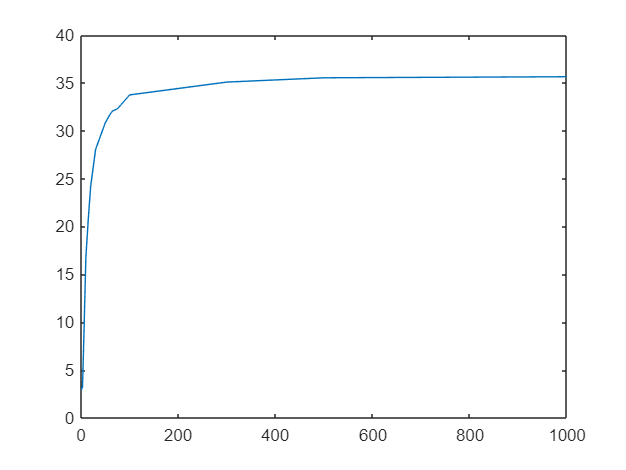

imagefiles = dir("CroppedYale/CroppedYale/*/*");
nfiles = length(imagefiles);
imagefolders = dir("CroppedYale/CroppedYale");
nfolders = length(imagefolders);

train = double(zeros(192*168, 1));
test = double(zeros(192*168, 1));
train_index = 1;
test_index = 1;
for i=3:nfolders
   files = dir("CroppedYale/CroppedYale/"+imagefolders(i).name);
   nimages = length(files);
   count(i-2) = nimages-2-40;
   for j=3:nimages
       if j<=42
           im = double(imread("CroppedYale/CroppedYale/"+imagefolders(i).name+"/"+files(j).name));
           train(:, train_index) = reshape(im',1,  [])';
           train_index = train_index + 1;
       else
           im = double(imread("CroppedYale/CroppedYale/"+imagefolders(i).name+"/"+files(j).name));
           test(:, test_index) = reshape(im', 1, [])';
           test_index = test_index + 1;
       end
   end
end

ks =[1, 2, 3, 5, 10, 15, 20, 30, 50, 60, 65, 75, 100, 200, 300, 500, 1000];
[acc1, acc2] = PCA3(train, test, ks, count);
plot(ks, acc1)

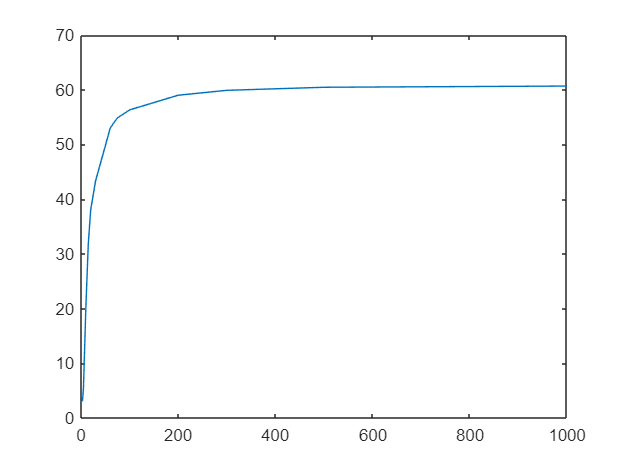

plot(ks, acc2);